% Analytic_strain_modeling2.mlx
% No moire rotation will be considered in this workbook.

syms tr x y
trxy = exp(-x^2-y^2)*tr;
rotmat_r1 = [cos(trxy/2), -sin(trxy/2); sin(trxy/2), cos(trxy/2)];
rotmat_r2 = [cos(trxy/2), sin(trxy/2); -sin(trxy/2), cos(trxy/2)];

a1_0 = [x;y];
a2_0 = [x;y];

a1 = rotmat_r1*a1_0;
a2 = rotmat_r2*a2_0;

u_observed = a1 - a2

$$u\_observed = \left(\begin{array}{c} -2\,y\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)\\ 2\,x\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right) \end{array}\right)$$

ua1 = a1 - a1_0

$$ua1 = \left(\begin{array}{c} x\,\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)-x-y\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)\\ y\,\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)-y+x\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right) \end{array}\right)$$

ua2 = a2 - a2_0

$$ua2 = \left(\begin{array}{c} x\,\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)-x+y\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)\\ y\,\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)-y-x\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right) \end{array}\right)$$


exx_observed = simplify(diff(u_observed(1),x))

$$exx\_observed = 2\,\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)$$

exx_a1 = diff(ua1(1),x)

$$exx\_a1 = \cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)+\mathrm{tr}\,x^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)+\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)-1$$

exx_a2 = diff(ua2(1),x)

$$exx\_a2 = \cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)+\mathrm{tr}\,x^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)-\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)-1$$

## Visualization

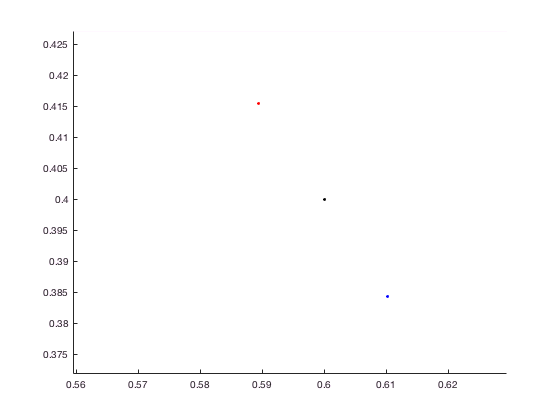

xbase = -2:0.1:2;
ybase = -2:0.1:2;
[xspace,yspace] = meshgrid(xbase,ybase);
a1x_fcn = matlabFunction(a1(1));
a1y_fcn = matlabFunction(a1(2));
a2x_fcn = matlabFunction(a2(1));
a2y_fcn = matlabFunction(a2(2));
thetar = deg2rad(5);
a1xpoints_afterrot = a1x_fcn(thetar,xspace,yspace);
a1ypoints_afterrot = a1y_fcn(thetar,xspace,yspace);
a2xpoints_afterrot = a2x_fcn(thetar,xspace,yspace);
a2ypoints_afterrot = a2y_fcn(thetar,xspace,yspace);

figure;
hold on
scatter(xspace(:),yspace(:),10,'k','filled');
scatter(a1xpoints_afterrot(:),a1ypoints_afterrot(:),10,'r','filled');
scatter(a2xpoints_afterrot(:),a2ypoints_afterrot(:),10,'b','filled');
axis equal


% The visual logic seems good enough. I suspect the issue being the triangle that is formed?
% It suggests the sum of the norms of the displacements for the two layers exceeds the norm of the two layers.
% But what if the rotation occurred on a line, rather than a circle? This may be modeled by the small angle approximation.

## Small angle approximation

rotmat_sr1 = [1, -trxy/2; trxy/2, 1];
rotmat_sr2 = [1, trxy/2; -trxy/2, 1];
a1s = rotmat_sr1*a1_0;
a2s = rotmat_sr2*a2_0;
u_observed_s = a1s - a2s

$$u\_observed\_s = \left(\begin{array}{c} -\mathrm{tr}\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\\ \mathrm{tr}\,x\,{\mathrm{e}}^{-x^{2}-y^{2}} \end{array}\right)$$

ua1s = a1s - a1_0

$$ua1s = \left(\begin{array}{c} -\frac{\mathrm{tr}\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\\ \frac{\mathrm{tr}\,x\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2} \end{array}\right)$$

ua2s = a2s - a2_0

$$ua2s = \left(\begin{array}{c} \frac{\mathrm{tr}\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\\ -\frac{\mathrm{tr}\,x\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2} \end{array}\right)$$

exx_observed_s = simplify(diff(u_observed_s(1),x))

$$exx\_observed\_s = 2\,\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

exx_a1s = diff(ua1s(1),x)

$$exx\_a1s = \mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

exx_a2s = diff(ua2s(1),x)

$$exx\_a2s = -\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

% This looks excellent! 


## Small angle approximation visualization

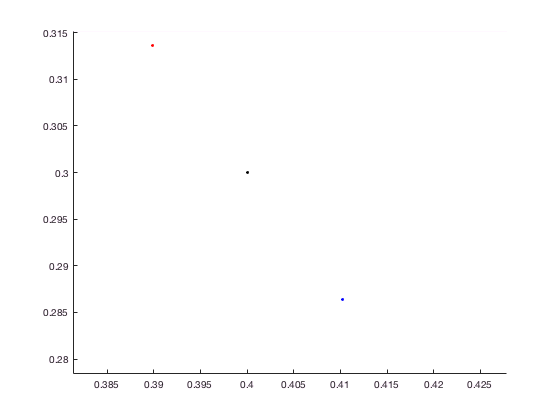

a1sx_fcn = matlabFunction(a1s(1));
a1sy_fcn = matlabFunction(a1s(2));
a2sx_fcn = matlabFunction(a2s(1));
a2sy_fcn = matlabFunction(a2s(2));
thetar = deg2rad(5);
a1sxpoints_afterrot = a1sx_fcn(thetar,xspace,yspace);
a1sypoints_afterrot = a1sy_fcn(thetar,xspace,yspace);
a2sxpoints_afterrot = a2sx_fcn(thetar,xspace,yspace);
a2sypoints_afterrot = a2sy_fcn(thetar,xspace,yspace);

figure;
hold on
scatter(xspace(:),yspace(:),10,'k','filled');
scatter(a1xpoints_afterrot(:),a1sypoints_afterrot(:),10,'r','filled');
scatter(a2xpoints_afterrot(:),a2sypoints_afterrot(:),10,'b','filled');
axis equal

## Validate relationship for other strain elements

exy_observed_s = simplify(diff(u_observed_s(1),y))

$$exy\_observed\_s = \mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(2\,y^{2}-1\right)$$

exy_a1s = diff(ua1s(1),y)

$$exy\_a1s = \mathrm{tr}\,y^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}-\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}$$

exy_a2s = diff(ua2s(1),y)

$$exy\_a2s = \frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}-\mathrm{tr}\,y^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

ratio = simplify(exy_observed_s/(exy_a1s-exy_a2s))
eyx_observed_s = simplify(diff(u_observed_s(2),x))

$$eyx\_observed\_s = -\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(2\,x^{2}-1\right)$$

eyx_a1s = diff(ua1s(2),x)

$$eyx\_a1s = \frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}-\mathrm{tr}\,x^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

eyx_a2s = diff(ua2s(2),x)

$$eyx\_a2s = \mathrm{tr}\,x^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}-\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}$$

ratio = simplify(eyx_observed_s/(eyx_a1s-eyx_a2s))
eyy_observed_s = simplify(diff(u_observed_s(2),y))

$$eyy\_observed\_s = -2\,\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

eyy_a1s = diff(ua1s(2),y)

$$eyy\_a1s = -\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

eyy_a2s = diff(ua2s(2),y)

$$eyy\_a2s = \mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

ratio = simplify(eyy_observed_s/(eyy_a1s-eyy_a2s))
